% PROBLEM 1-B

% Clear workspace
close all
clear
clc

% Add parser and solver to path
addpath(genpath('C:\Users\tsamak\Downloads\MathWorks\Toolboxes\archives\required\YALMIP'))
addpath(genpath('C:\Users\tsamak\Downloads\MathWorks\Toolboxes\archives\required\SeDuMi'))

% Define the system matrices
A = [-4, 2; 1, -7];
K = [1; 1];
M = [1, 0];
H = 0;

% Define the LMI variables
P = sdpvar(2, 2);
gamma = sdpvar(1, 1);

% Define the LMI constraints
LMI1 = [P*A+A'*P, P*K, M'; K'*P, -gamma*eye(1), H'; M, H, -gamma*eye(1)] <= 0;
LMI2 = P >= 0;

% Set up the objective
Objective = gamma;

% Define the solver settings (use an LMI solver like YALMIP with a solver of your choice)
options = sdpsettings('verbose', 1, 'solver', 'sedumi');

% Solve the LMI problem
solution = optimize([LMI1, LMI2], Objective, options);

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 4, order n = 7, dim = 21, blocks = 3
nnz(A) = 16 + 0, nnz(ADA) = 16, nnz(L) = 10
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.44E+01 0.000
  1 :  -1.04E+00 8.22E+00 0.000 0.2391 0.9000 0.9000   1.23  1  1  6.7E+00
  2 :  -4.16E-01 1.77E+00 0.000 0.2159 0.9000 0.9000   1.52  1  1  1.2E+00
  3 :  -3.39E-01 1.61E-01 0.000 0.0905 0.9900 0.9900   0.94  1  1  1.2E-01
  4 :  -3.46E-01 1.43E-02 0.311 0.0893 0.9900 0.9900   0.98  1  1  1.0E-02
  5 :  -3.46E-01 3.32E-03 0.000 0.2316 0.9000 0.9000   0.97  1  1  2.4E-03
  6 :  -3.46E-01 9.37E-05 0.000 0.0282 0.9900 0.9900   1.00  1  1  6.9E-05
  7 :  -3.46E-01 9.12E-06 0.125 0.0973 0.9450 0.9450   1.01  1  1  6.7E-06
  8 :  -3.46E-01 1.65E-06 0.051 0.1807 0.9000 0.9000   1.01  1  2  1.2E-06
  9 :  -3.46E-01 3.69E-08 0.000 0.0224 0.9900 0.9900   1.01  3  3  2.6E-08
 10 :  -3.46E-01 3.2


if solution.problem == 0
    % Extract the optimal solution
    optimal_gamma = 1/value(gamma);
    % Display the result
    fprintf('Optimal gamma: %.4f\n', optimal_gamma);
    fprintf('Stability guaranteed: %.4f < delta(t) < %.4f\n', -optimal_gamma, optimal_gamma);
else
    fprintf('LMI problem could not be solved.\n');
end

Optimal gamma: 2.8889


Stability guaranteed: -2.8889 < delta(t) < 2.8889


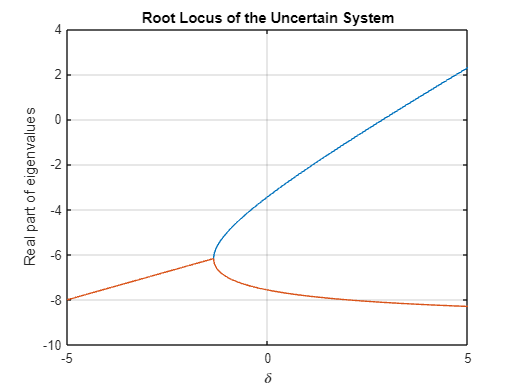

% PROBLEM 1-C

% Define delta limits and granularity
delta_values = linspace(-5, 5, 100000);
roots_real_part = zeros(length(delta_values), 2);
max_delta = -100; % Initialize max_delta for optimization

% Plot root locus for all delta values
for i = 1:length(delta_values)
    delta = delta_values(i);
    A = [-4 + delta, 2; 1 + delta, -7];
    roots_real_part(i, :) = real(eig(A));
    if (all(real(eig(A)) < 0)) && (delta > max_delta)
        max_delta = delta; % Optimize max_delta
    end
end

% Create root locus plot
figure;
plot(delta_values, roots_real_part);
xlabel('\delta');
ylabel('Real part of eigenvalues');
title('Root Locus of the Uncertain System');
grid on;


% Print result
fprintf('Optimal delta: %.4f\n', max_delta);

Optimal delta: 2.8889


% PROBLEM 1-D

% Define the system matrices
A = [0, 1; -1, -0.2];
K = [0; 1];
M = [0.5, 0];
H = 0;

% Define the LMI variables
P = sdpvar(2, 2);
gamma = sdpvar(1, 1);

% Define the LMI constraints
LMI1 = [P*A+A'*P, P*K, M'; K'*P, -gamma*eye(1), H'; M, H, -gamma*eye(1)] <= 0;
LMI2 = P >= 0;

% Set up the objective
Objective = gamma;

% Define the solver settings (use an LMI solver like YALMIP with a solver of your choice)
options = sdpsettings('verbose', 1, 'solver', 'sedumi');

% Solve the LMI problem
solution = optimize([LMI1, LMI2], Objective, options);

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 4, order n = 7, dim = 21, blocks = 3
nnz(A) = 13 + 0, nnz(ADA) = 16, nnz(L) = 10
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.89E+00 0.000
  1 :  -7.82E-01 6.51E-01 0.000 0.2252 0.9000 0.9000   1.40  1  1  1.2E+00
  2 :  -1.19E+00 1.86E-01 0.000 0.2859 0.9000 0.9000   0.83  1  1  3.3E-01
  3 :  -1.80E+00 4.22E-02 0.000 0.2264 0.9000 0.9000   0.36  1  1  1.1E-01
  4 :  -2.27E+00 8.54E-03 0.000 0.2025 0.9000 0.9000   0.47  1  1  3.2E-02
  5 :  -2.49E+00 4.91E-04 0.000 0.0575 0.9900 0.9900   0.77  1  1  2.1E-03
  6 :  -2.51E+00 1.21E-05 0.030 0.0246 0.9900 0.9900   0.98  1  1  5.1E-05
  7 :  -2.51E+00 4.06E-07 0.465 0.0337 0.9900 0.9900   1.00  1  1  1.7E-06
  8 :  -2.51E+00 2.24E-08 0.192 0.0551 0.9900 0.9900   1.00  2  2  9.5E-08
  9 :  -2.51E+00 7.42E-10 0.030 0.0332 0.9900 0.9900   1.00  2  2  3.1E-09
 10 :  -2.51E+00 5.3


if solution.problem == 0
    % Extract the optimal solution
    optimal_gamma = 1/value(gamma);
    % Display the result
    fprintf('Optimal gamma: %.4f\n', optimal_gamma);
    fprintf('Stability guaranteed: %.4f < delta(t) < %.4f\n', -optimal_gamma, optimal_gamma);
else
    fprintf('LMI problem could not be solved.\n');
end

Optimal gamma: 0.3980


Stability guaranteed: -0.3980 < delta(t) < 0.3980


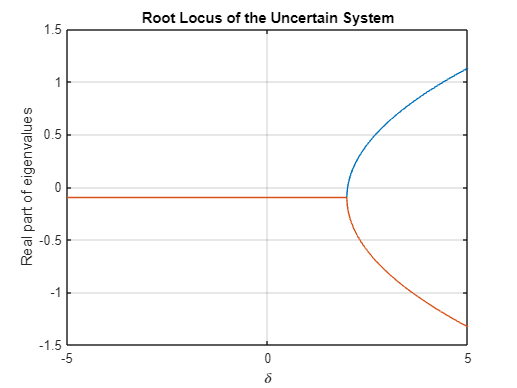


% Define delta limits and granularity
delta_values = linspace(-5, 5, 100000);
roots_real_part = zeros(length(delta_values), 2);
max_delta = -100; % Initialize max_delta for optimization

% Plot root locus for all delta values
for i = 1:length(delta_values)
    delta = delta_values(i);
    A = [0, 1; -1 + 0.5*delta, -0.2];
    roots_real_part(i, :) = real(eig(A));
    if (all(real(eig(A)) < 0)) && (delta > max_delta)
        max_delta = delta; % Optimize max_delta
    end
end

% Create root locus plot
figure;
plot(delta_values, roots_real_part);
xlabel('\delta');
ylabel('Real part of eigenvalues');
title('Root Locus of the Uncertain System');
grid on;


% Print result
fprintf('Optimal delta: %.4f\n', max_delta);

Optimal delta: 2.0000


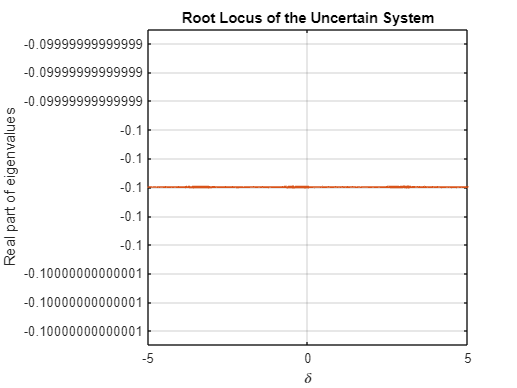

% PROBLEM 1-E

% Define time array for simulation
time = linspace(0, 10, 100000);
roots_real_part = zeros(length(delta_values), 2);
max_delta = -100; % Initialize max_delta for optimization

% Plot root locus for all delta values
for i = 1:length(time)
    delta = cos(time(i));
    A = [0, 1; -1 + 0.5*delta, -0.2];
    roots_real_part(i, :) = real(eig(A));
    if (all(real(eig(A)) < 0)) && (delta > max_delta)
        max_delta = delta; % Optimize max_delta
    end
end

% Create root locus plot
figure;
plot(delta_values, roots_real_part);
xlabel('\delta');
ylabel('Real part of eigenvalues');
title('Root Locus of the Uncertain System');
grid on;


% Print result
fprintf('Optimal delta: %.4f\n', max_delta);

Optimal delta: 1.0000
